function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    %SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1:2,'SARLags',[147,294],'Seasonality',147,'SMALags',[147,294],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end

function SARIMA_D4 = model_D4(D4)
    D41 = D4(:,1);
    SARIMA_D4 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D4 = estimate(SARIMA_D4,D41,'Display','off');
end

function SARIMA_D317 = model_D3(D3)
    D31 = D3(:,1);
    SARIMA_D317 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D317 = estimate(SARIMA_D317,D31,'Display','off');
end

function SARIMA_D21 = model_D2(D2)
    D21 = D2(:,1);
    SARIMA_D21 = arima('Constant',NaN,'ARLags',1,'D',0,'MALags',[],'SARLags',42,'Seasonality',42,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D21 = estimate(SARIMA_D21,D21,'Display','off');
end

function SARIMA_D112 = model_D1(D1)
    D11 = D1(:,1);
    SARIMA_D112 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[],'SARLags',[21,42],'Seasonality',42*4,'SMALags',[],'Distribution','Gaussian');
    SARIMA_D112 = estimate(SARIMA_D112,D11,'Display','off');
end

function SARIMA_A113 = model_A1(A1)
    A11 = A1(:,1);
    SARIMA_A113 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',1,'SARLags',50,'Seasonality',50,'SMALags',50,'Distribution','Gaussian');
    SARIMA_A113 = estimate(SARIMA_A113,A11,'Display','off');
end

function predictions = model_HoltWinters(y_train, y_test, step_length, seasonal_periods)
    py_model = py.importlib.import_module('HoltWintersModule');
    predictions_py = py_model.forecast_holt_winters(y_train, y_test, step_length, seasonal_periods);
    predictions = double(predictions_py);
end


% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);


$$$R^2_{\text{classic}} = 1 - \frac{\sum_i (y_i - \hat{y}_i)^2}{\sum_i (y_i - \bar{y})^2}$$$



$$$R^2_{\text{alt}} = \frac{\sum_{i=1}^{n} (\hat{y}_i - \bar{y})^2}{\sum_{i=1}^{n} (y_i - \bar{y})^2}$.

$$


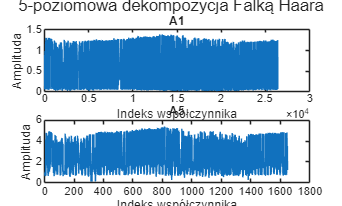

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% 2. RYSOWANIE WYKRESÓW
figure;

subplot(2, 1, 1);
plot(A1);
title('A1');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

subplot(2, 1, 2);
plot(A5);
title('A5');
xlabel('Indeks współczynnika');
ylabel('Amplituda');

sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

forecast_horizont = 32 * 542;

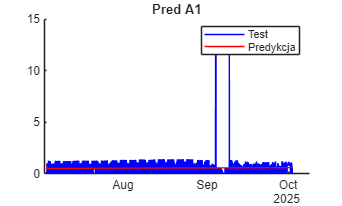

% Przewidywania A1
Mdl_A1 = model_A5(A1);
A1_pred = forecast(Mdl_A1, forecast_horizont/2, 'Y0', A1);

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:length(A1_test)), A1_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(A1_pred)), A1_pred, 'Color','red','DisplayName','Predykcja');
title('Pred A1');
legend;

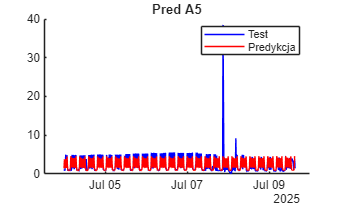

% Przewidywania A5
Mdl_D5 = model_A5(A5);
A5_pred = forecast(Mdl_D5, forecast_horizont/32, 'Y0', A5);

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:length(A5_test)), A5_test, 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:length(A5_pred)), A5_pred, 'Color','red','DisplayName','Predykcja');
title('Pred A5');
legend;

A5_pred_col = A5_pred(:);
D5_pred_col = zeros(forecast_horizont/32, 1);
D4_pred_col = zeros(forecast_horizont/16, 1);
D3_pred_col = zeros(forecast_horizont/8, 1);
D2_pred_col = zeros(forecast_horizont/4, 1);
%D1_pred_col = zeros(forecast_horizont/2, 1);
D1_pred_col = model_HoltWinters(D1', D1_test', 96, 96)';

Rozpoczynanie prognozy (Refitting Expanding Window)...
Rozmiar testowy: 8688, Krok: 96, Pętle: 91
  Pętla 1/91 (Rozmiar danych tren.: 26399)...
  Pętla 2/91 (Rozmiar danych tren.: 26495)...
  Pętla 3/91 (Rozmiar danych tren.: 26591)...
  Pętla 4/91 (Rozmiar danych tren.: 26687)...
  Pętla 5/91 (Rozmiar danych tren.: 26783)...
  Pętla 6/91 (Rozmiar danych tren.: 26879)...
  Pętla 7/91 (Rozmiar danych tren.: 26975)...
  Pętla 8/91 (Rozmiar danych tren.: 27071)...
  Pętla 9/91 (Rozmiar danych tren.: 27167)...
  Pętla 10/91 (Rozmiar danych tren.: 27263)...
  Pętla 11/91 (Rozmiar danych tren.: 27359)...
  Pętla 12/91 (Rozmiar danych tren.: 27455)...
  Pętla 13/91 (Rozmiar danych tren.: 27551)...
  Pętla 14/91 (Rozmiar danych tren.: 27647)...
  Pętla 15/91 (Rozmiar danych tren.: 27743)...
  Pętla 16/91 (Rozmiar danych tren.: 27839)...
  Pętla 17/91 (Rozmiar danych tren.: 27935)...
  Pętla 18/91 (Rozmiar danych tren.: 28031)...
  Pętla 19/91 (Rozmiar danych tren.: 28127)...
  Pętla 20/91 (Roz

A1_pred_col = model_HoltWinters(A1', A1_test', 96, 96)';

Rozpoczynanie prognozy (Refitting Expanding Window)...
Rozmiar testowy: 8688, Krok: 96, Pętle: 91
  Pętla 1/91 (Rozmiar danych tren.: 26399)...
  Pętla 2/91 (Rozmiar danych tren.: 26495)...
  Pętla 3/91 (Rozmiar danych tren.: 26591)...
  Pętla 4/91 (Rozmiar danych tren.: 26687)...
  Pętla 5/91 (Rozmiar danych tren.: 26783)...
  Pętla 6/91 (Rozmiar danych tren.: 26879)...
  Pętla 7/91 (Rozmiar danych tren.: 26975)...
  Pętla 8/91 (Rozmiar danych tren.: 27071)...
  Pętla 9/91 (Rozmiar danych tren.: 27167)...
  Pętla 10/91 (Rozmiar danych tren.: 27263)...
  Pętla 11/91 (Rozmiar danych tren.: 27359)...
  Pętla 12/91 (Rozmiar danych tren.: 27455)...
  Pętla 13/91 (Rozmiar danych tren.: 27551)...
  Pętla 14/91 (Rozmiar danych tren.: 27647)...
  Pętla 15/91 (Rozmiar danych tren.: 27743)...
  Pętla 16/91 (Rozmiar danych tren.: 27839)...
  Pętla 17/91 (Rozmiar danych tren.: 27935)...
  Pętla 18/91 (Rozmiar danych tren.: 28031)...
  Pętla 19/91 (Rozmiar danych tren.: 28127)...
  Pętla 20/91 (Roz

% Krok 2: Zbuduj jeden wektor współczynników `c_pred`
% Kolejność musi być identyczna jak w strukturze [c,l] z wavedec:
% [A_n | D_n | D_n-1 | ... | D_1]
c_pred = [
    A5_pred_col;
    D5_pred_col;
    D4_pred_col;
    D3_pred_col;
    D2_pred_col;
    D1_pred_col
];

l_pred = [
    length(A5_pred_col);
    length(D5_pred_col);
    length(D4_pred_col);
    length(D3_pred_col);
    length(D2_pred_col);
    length(D1_pred_col);
    length(c_pred)
];

%final_prediction = waverec(c_pred', l_pred', 'haar');
final_prediction = idwt(A1_pred_col', D1_pred_col', 'haar');

%pred_full = final_prediction';
pred_full = final_prediction(1:2880)'; % okres 1 miesiac

y_test = ab_diff_test_norm(1:length(pred_full))';

mae_score = mae(y_test, pred_full')

mae_score = 0.2421

mape_score = mape(y_test, pred_full')

mape_score = 119.9702

rmse_score = rmse(y_test, pred_full')

rmse_score = 0.2996

r2_classic = R2_classic(y_test, pred_full')

r2_classic = 0.2509

r2_alt = R2_alt(y_test, pred_full')

r2_alt = 0.4691

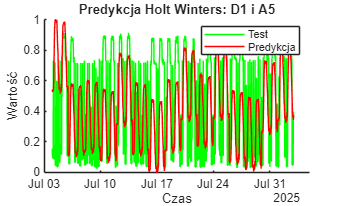


figure;
hold on;
%plot(ab_diff_train.Time, ab_diff_train_norm, 'Color','blue','DisplayName','Trening');
plot(ab_diff_test.Time(1:length(pred_full)), ab_diff_test_norm(1:length(pred_full)), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:length(pred_full)), pred_full, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja Holt Winters: D1 i A5")
legend;

% POPRAWKA 1: Użyj nazwy swojego zestawu danych (zakładam, że 'ab')
data_names = {'ab'}; % To utworzy plik 'pred_ab_HW-ELM_4-96.xlsx'

% POPRAWKA 2: Zdefiniuj nazwy miar i ich obliczone wartości
measures_names = ["MAE"; "MAPE"; "RMSE"; "R2_classic"; "R2_alternative"];
measures_values = [mae_score; mape_score; rmse_score; r2_classic; r2_alt];

% POPRAWKA 3: Utwórz tabelę metryk z obliczonymi wartościami
T_metrics = table(measures_values, 'RowNames', measures_names, 'VariableNames', {'Wartosc'});
metrics_cell = {T_metrics};

% POPRAWKA 4: Przekaż dane TESTOWE ('y_test'), a nie treningowe
original_data_cell = {y_test}; 
prediction_data_cell = {pred_full};


% Wywołaj funkcję zapisu
zapiszWynikiPrognozy(data_names, original_data_cell, prediction_data_cell, metrics_cell);

Rozpoczynanie zapisu wyników...
Pomyślnie zapisano: .\output\predictions\pred_ab_HW.xlsx

Zakończono zapis wszystkich wyników.
